% This script demonstrates conformance checking using measurements from a
% platoon and compared different set representations for the model
% uncertainties

% load measurements from the car
load('measurements_platoon');

% algorithm settings
Opts = [];
Opts.group = 6;         % number of measurement grouped together
Opts.measErr = true;    % use measurement errors to represent uncertainty
Opts.mu = 0.1;          % trade-off measurement error and process noise 

% conformance checking (interval)
clock = tic;
Opts.set = 'interval';
[Wint,Vint] = conformantSynthesis('platoon',M,Opts);
tComp = toc(clock);

disp(['Computation time (interval): ',num2str(tComp)]);

Computation time (interval): 1.933



% conformance checking (zonotope)
clock = tic;
Opts.set = 'zonotope';
Wzono = conformantSynthesis('platoon',M,Opts);
tComp = toc(clock);

disp(['Computation time (zonotope): ',num2str(tComp)]);

Computation time (zonotope): 1.8522


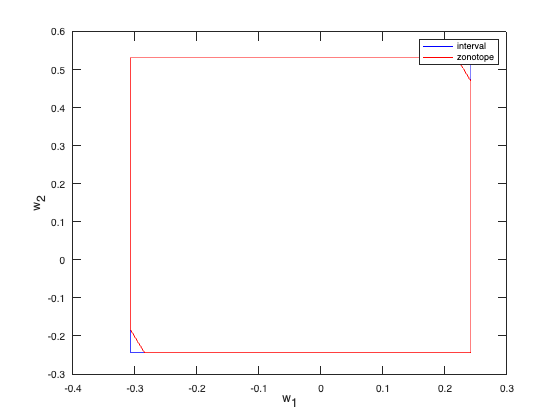


% visualization
figure; hold on; box on;
h1 = plot(Wint,[1,2],'b');
h2 = plot(Wzono,[1,2],'r');
legend([h1,h2],'interval','zonotope');
xlabel('w_1'); ylabel('w_2');

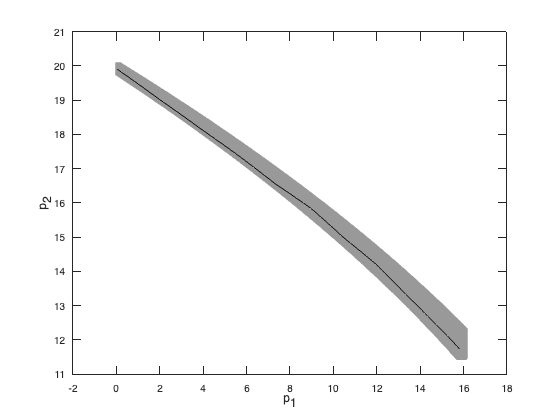


figure; hold on; box on;
R = reachSetConformance('platoon',M{1},Wint,Vint);
plot(R,[1,2],'FaceColor',[.6 .6 .6],'EdgeColor','none');
plot(M{1}.x(1,:),M{1}.x(2,:),'k');
xlabel('p_1'); ylabel('p_2');